# Hilbert Transform

## What is Hilbert Transform?

The discrete Hilbert transform is a process used to generate complex-valued signals from real-valued signals.

It is a method for extracting the magnitude and phase information from a real-valued signal like a EEG data:

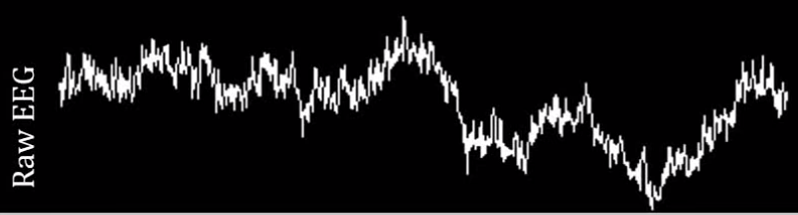

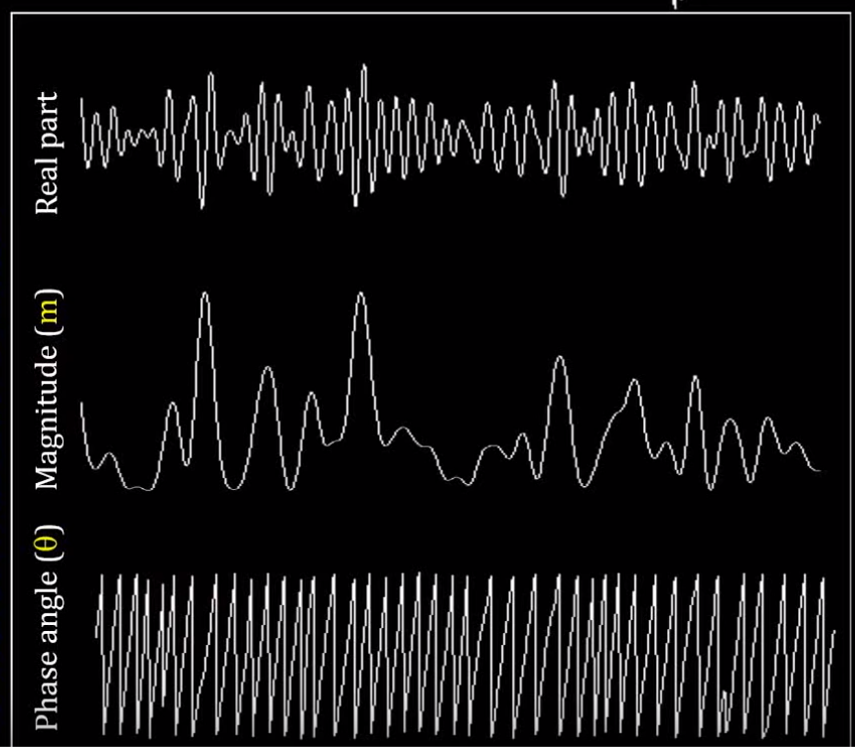

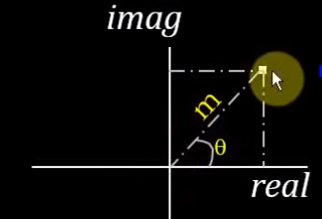

Notation used to define the continuous Hilbert transform:

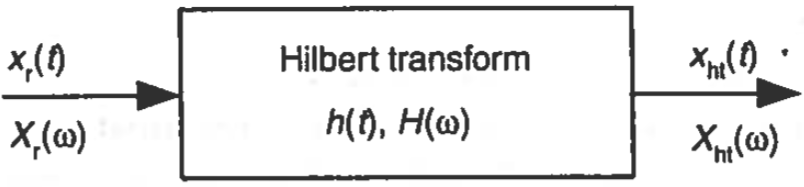

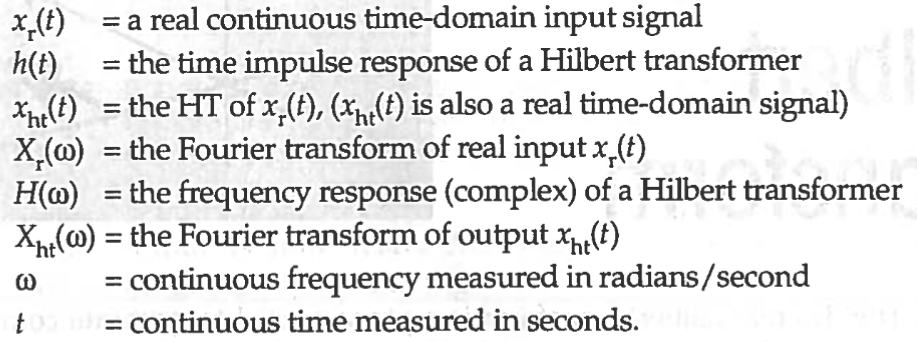

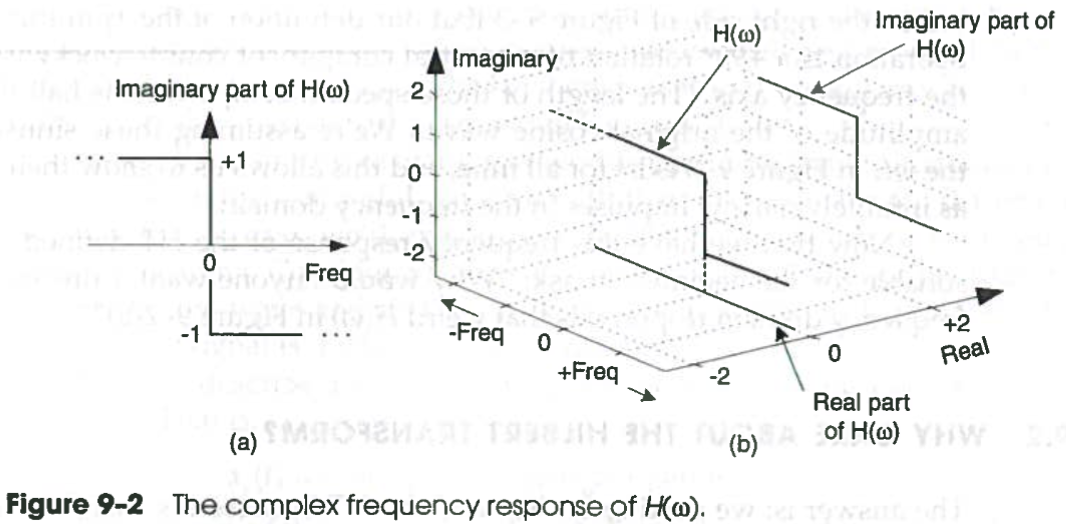

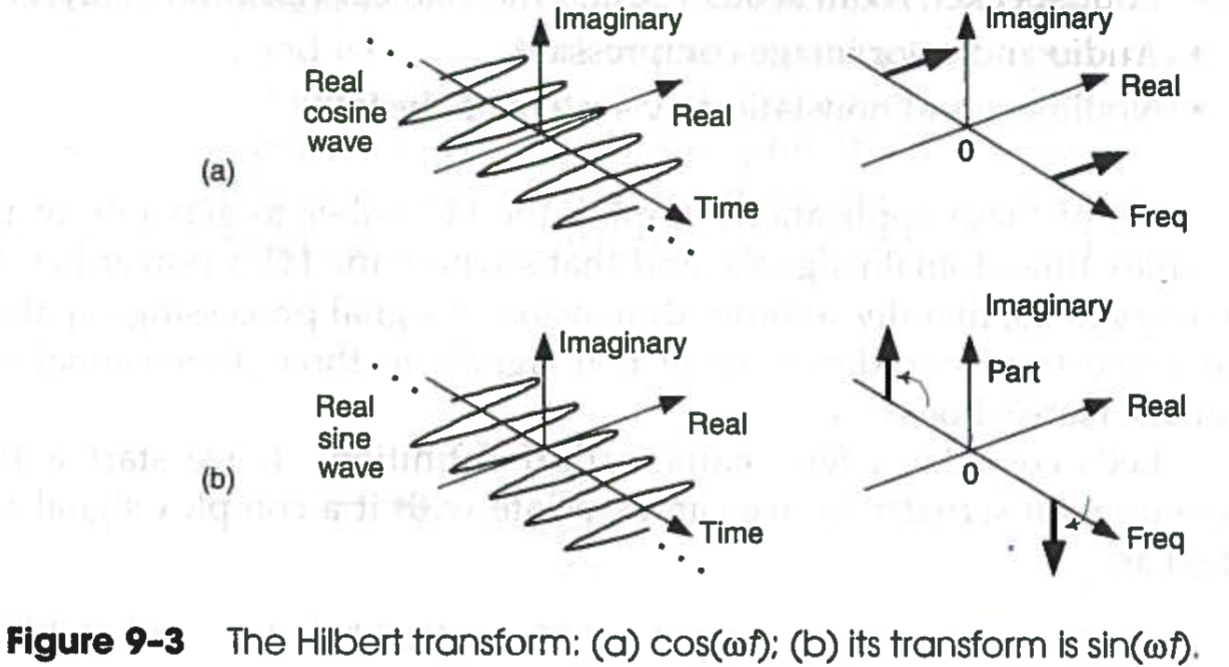

## Why do we need it?

Typically, we start with a real-valued signal which can be conceptualised as:

        
$$x_r \left(t\right)=A\;\mathrm{cos}\left(\omega \;t\right)$$


Given a real-value signal, we cannot estimate or extract the phase angle and the power. What we need to represent the signal as a complex sinusoid using Euler's formula:

        
$$x_c \left(t\right)=A\;e^{j\omega t}$$


        
$$x_c \left(t\right)=A\;\mathrm{cos}\left(\omega \;t\right)+j\;A\;\mathrm{sin}\left(\omega t\right)$$


        
$$x_c \left(t\right)=x_r \left(t\right)+j\;x_i \left(t\right)$$


where 

- $x_c \left(t\right)$ is known as an *analytic signal* because it has no negative-frequency spectral components. This means that $X_c \left(e^{j\omega } \right)$ is zero over the negative frequency range. This is also known as a *one-sided spectrum*.

- $j\;x_i \left(t\right)$ is called the *phase-quadrature component*.

Using complex signals of the real signals simplifies and improves the performance of many signal processing operations.

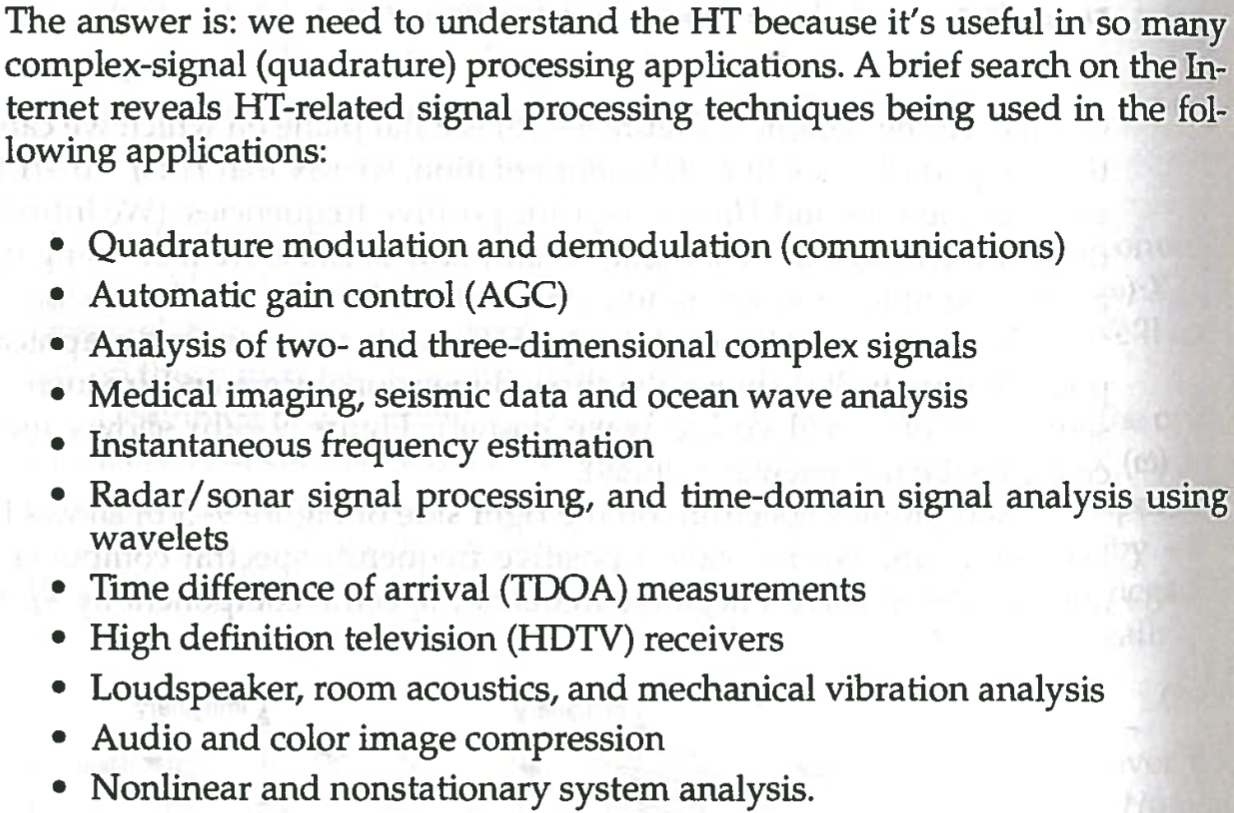

## Real Signals as Complex Exponentials

A real-valued signal can be seen as a a single frequency phasor (red) that is composed of the sum of two phasors:

- a positive frequency phasor (blue) rotates counter-clockwise

- a negative frequency phasor (green) rotates clockwise

        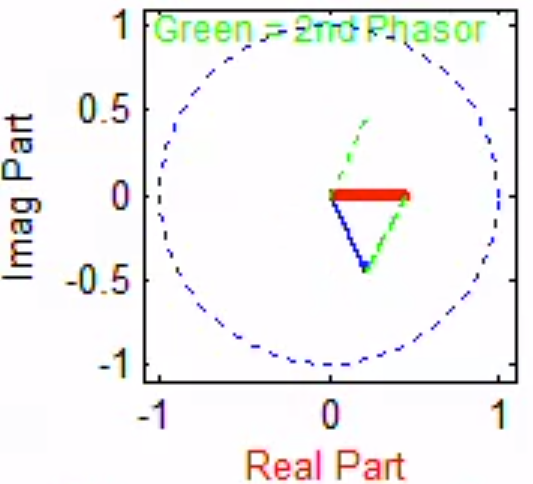           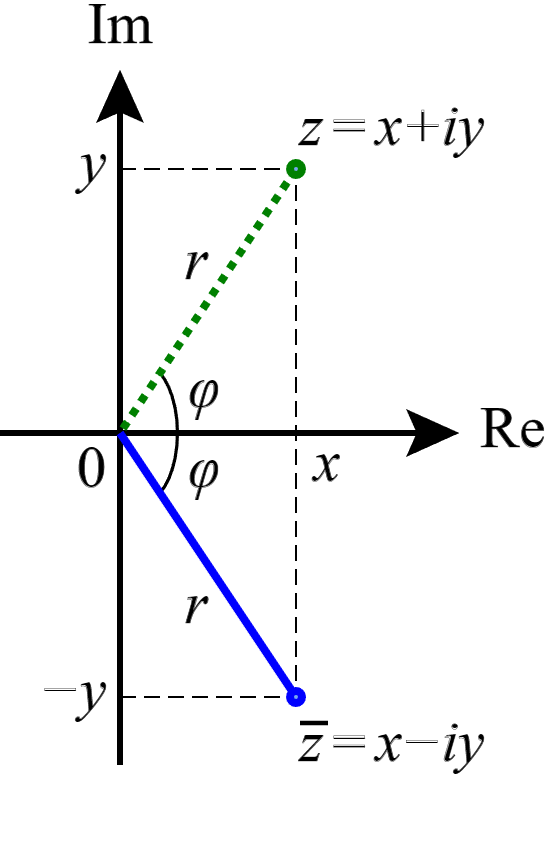

If we project the sum of the two phasors in the real part, we get the red phasor. However, if we project the sum into the imaginary part, the two phasors cancel out one another and we get zero imaginary component.

This means that a real-valued signal has two complex exponentials (complex conjugate phasors) rotating in oppsite directions. The real parts are in phase and sum together, the imaginary parts are opposite polarity, and cancel out, which leaves only a real sinusoid as a result. The negative and positive frequency components ***are*** both necessary to produce the real signal.

A real cosine signal $x_r \left(t\right)=A\;\mathrm{cos}\left(\omega_0 t+\phi \right)$ can be expressed in terms of two complex exponentials using Eulers formula:

        
$$x_r \left(t\right)=A\;\mathrm{cos}\left(\omega_0 t+\phi \right)\;$$


        
$$x_r \left(t\right)=A\;\left(\frac{e^{j\left(\omega t+\phi \right)} +e^{-j\left(\omega +\phi \right)} }{2}\right)\;$$


        
$$x_r \left(t\right)=A\;\left(\frac{1}{2}e^{j\left(\omega t+\phi \right)} +\frac{1}{2}e^{-j\left(\omega t+\phi \right)} \right)\;$$


        
$$x_r \left(t\right)=A\;\left(\frac{1}{2}e^{j\phi } e^{j\omega t} +\frac{1}{2}e^{-j\phi } e^{-j\omega t} \right)\;$$


        $x_r \left(t\right)=\frac{1}{2}Xe^{j\omega t} +\frac{1}{2}X^* e^{-j\omega t} \;$ where $X=Ae^{j\phi }$ and $X^* =Ae^{-j\phi }$

where $X^*$ is complex conjucate of the phasor $X$. This shows that a real-valued signal with frequency $\omega \;$ is actually composed for a positive frequency $+\omega$ complex exponential and a negative frequency $-\omega$ complex exponential.

The phase-quadrature component can be obtained by a 90 degree (*quarter-cycle*) shift on the complex plan. 

The Hilbert transform of $\mathrm{cos}\left(\theta \right)$ is $\mathrm{sin}\left(\theta \right)$ i.e., a quarter-cycle shift.

        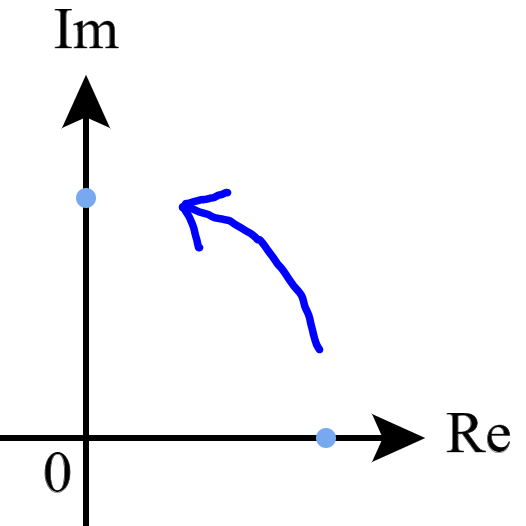

The Hilbert transform rotates the Fourier coefficients in the complex space which converts the real components into the imaginary component. The quarter-cycle shifted signal is then added to the original signal.

In other words, a Hilbert transform takes each frequency component present in the original signal and shifts its phase by $-\frac{\pi }{2}$.

For a continous time signal $x_r \left(t\right)$, the Hilbert transform is defined as:

        $x_{\mathrm{ht}} \left(t\right)=x_r \left(t\right)*\frac{1}{\pi t}$ where $*$ is the convolution operation

We can see the Hilbert transform as a FIR filter with the impulse response $h\left(t\right)=\frac{1}{\pi t}$

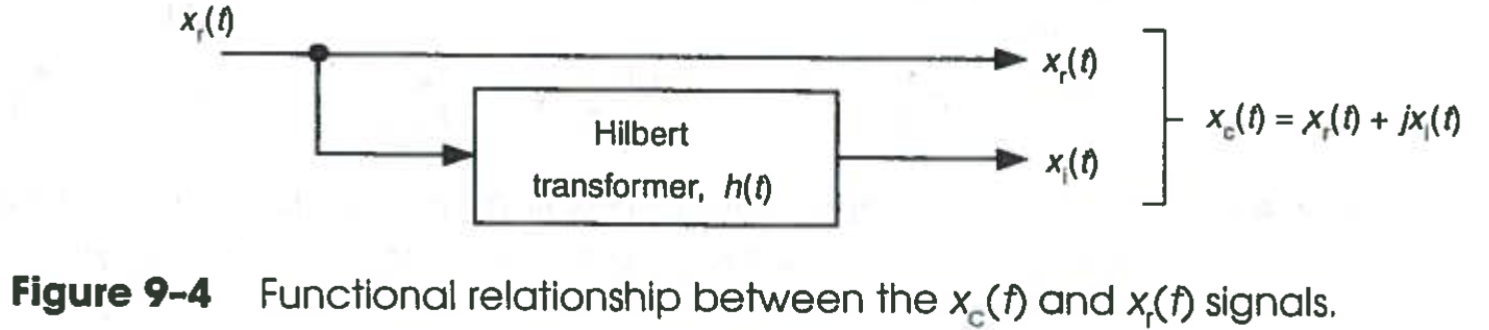

## FFT-based Hilbert transform

The FFT-based Hilbert transform can be implemented as three steps:

- Take the FFT of a time-series signal

- Rotate the Fourier coefficients

- Take the inverse FFT of the rotated Fourier coefficients to get a time-series signal

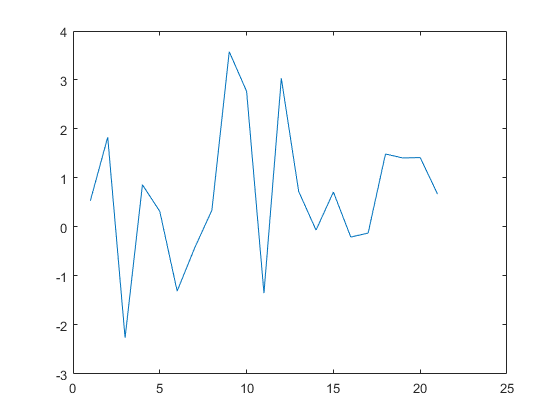

clear variables;

n = 21;

% Generate a signal
x = randn(n, 1);
plot(x)

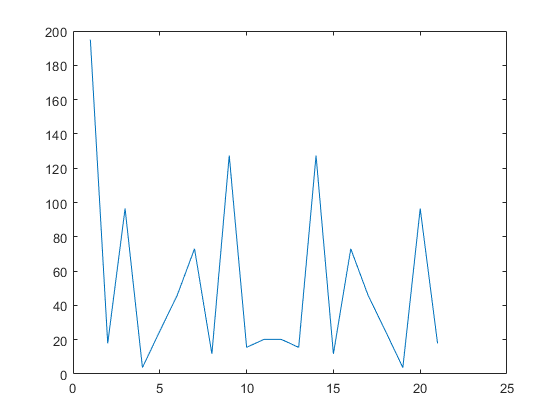



% Step 1: Take the FFT
f = fft(x);

plot(f.*conj(f))

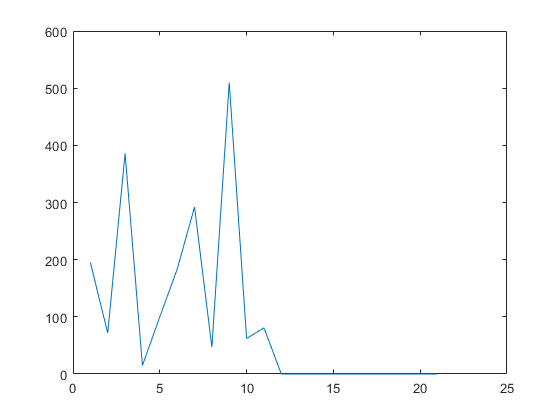


% Create a copy of the Fourier coefficients
complexf = 1i*f;

% Identify the indices for the positive and negative frequencies
% because they are rotated in different ways.
pos_freq_idx = 2:floor(n/2) + mod(n, 2);
neg_freq_idx = ceil(n/2) + 1 + ~mod(n, 2):n;

% Rotate the Fourier coefficients by computing i*A*sin(wt) component.
% Note! Positive frequencies are rotated counter-clockwise while
% negative frequencies are rotated clockwise.
f(pos_freq_idx) = f(pos_freq_idx) + -1i*complexf(pos_freq_idx);
f(neg_freq_idx) = f(neg_freq_idx) +  1i*complexf(neg_freq_idx);

plot(f.*conj(f))

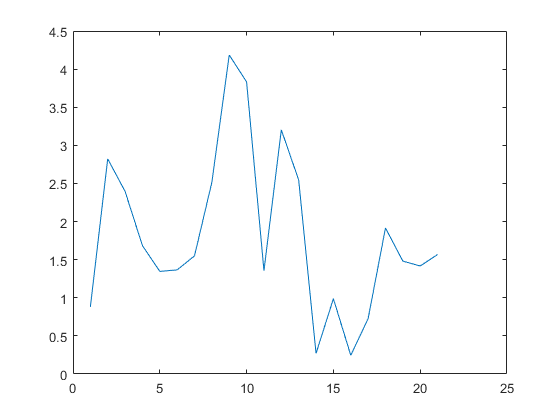


hilbert_x = ifft(f);

plot(abs(hilbert_x))

## Table of selected Hilbert transforms

In the following table, the frequency parameter $\omega$ is real. 

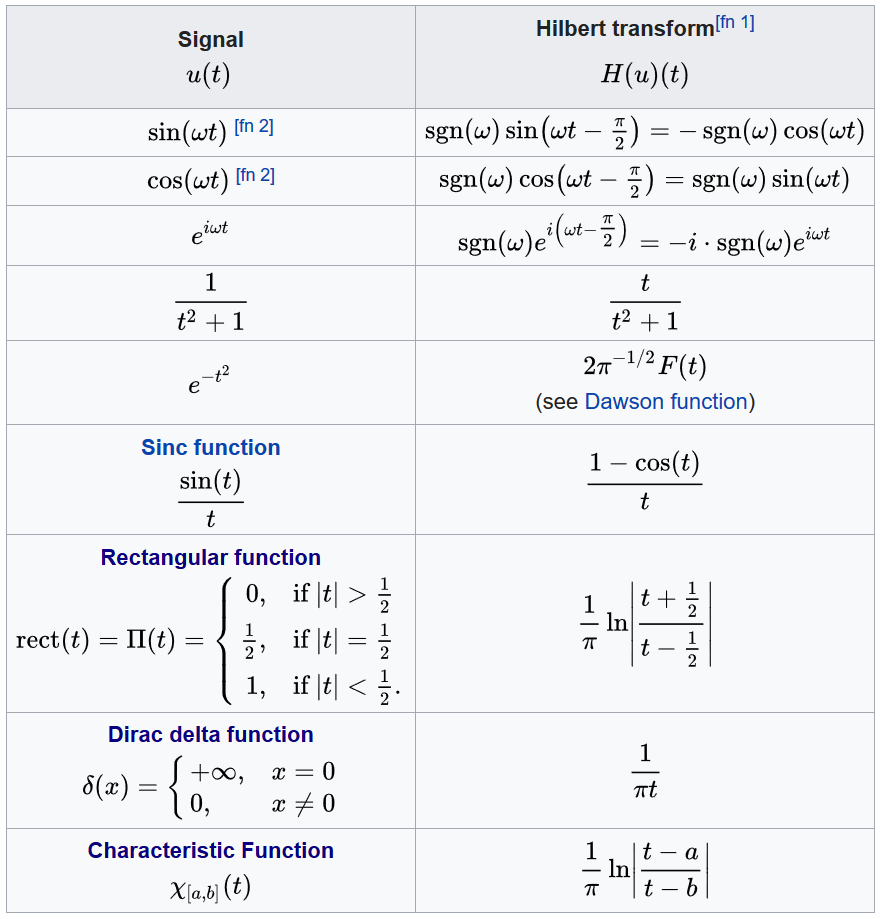

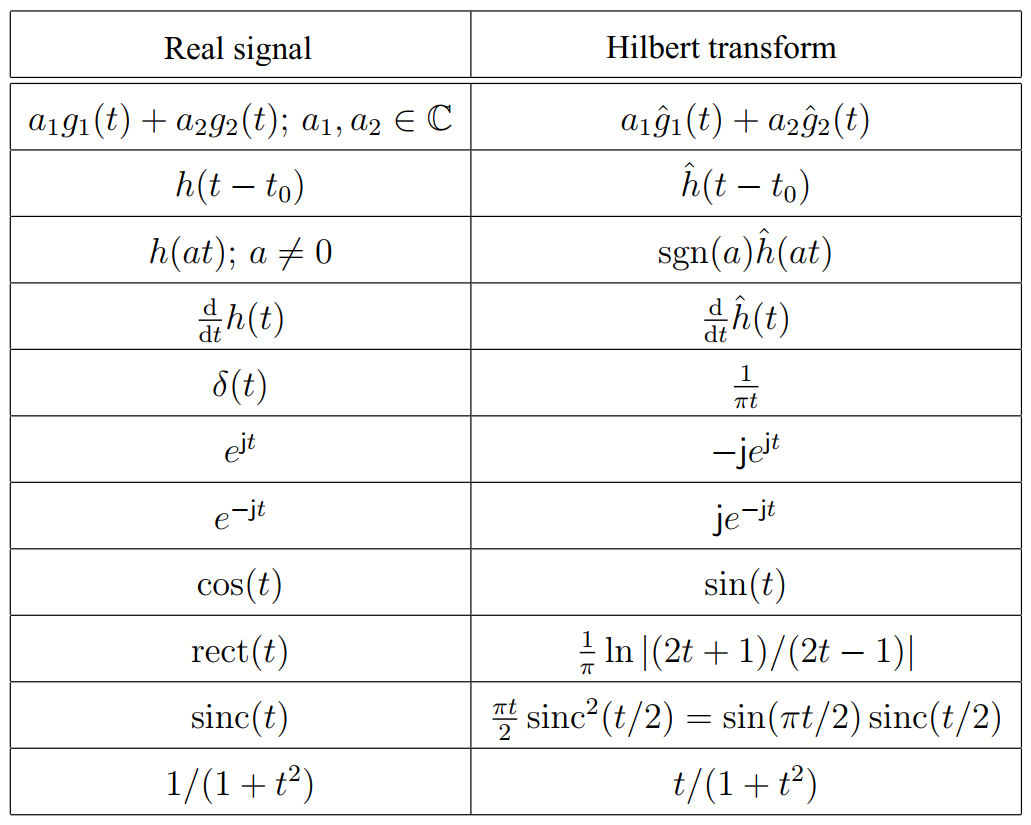

## Properties of the Hilbert transform

**(1)** A signal $x_r \left(t\right)$ and its Hilbert transform $x_i \left(t\right)$ have the **same power density spectrum**.

**(2)** A signal $x_r \left(t\right)$ and its Hilbert transform $x_i \left(t\right)$ have the **same autocorrelation function**.

**(3)** A signal $x_r \left(t\right)$ and its Hilbert transform $x_i \left(t\right)$ are mutually orthogonal so we can write: 

        
$$\int_{-\infty }^{\infty } x_r \left(t\right)x_i \left(t\right)\;\mathrm{dt}=0$$


**(4)** The effect of applying the Hilbert transform twice on a zero mean signal $x_r \left(t\right)$ is:

        
$$H\left\lbrack H\left\lbrack x_r \left(t\right)\right\rbrack \right\rbrack =-x_r \left(t\right)$$


For example, suppose $x_r \left(t\right)=\mathrm{cos}\left(t\right)$. Computing the Hilbert transform we get:

         
$$H\left\lbrack \mathrm{cos}\left(t\right)\right\rbrack =\mathrm{cos}\left(t-\frac{\pi }{2}\right)$$


Computing the Hilber transform again, we get:

         
$$H\left\lbrack \cos \left(t-\frac{\pi }{2}\right)\right\rbrack =\cos \left(t-\frac{\pi }{2}-\frac{\pi }{2}\right)$$


         
$$H\left\lbrack \cos \left(t-\frac{\pi }{2}\right)\right\rbrack =\cos \left(t-\pi \right)$$


         
$$H\left\lbrack \cos \left(t-\frac{\pi }{2}\right)\right\rbrack =-\cos \left(t\right)$$


**(5)** The energy of a Hilbert transform $x_i \left(t\right)$ is the same as the energy of the original signal $x_r \left(t\right)$. Hilbert Transform does not changes the magnitude of the input signal hence the energy is invariant

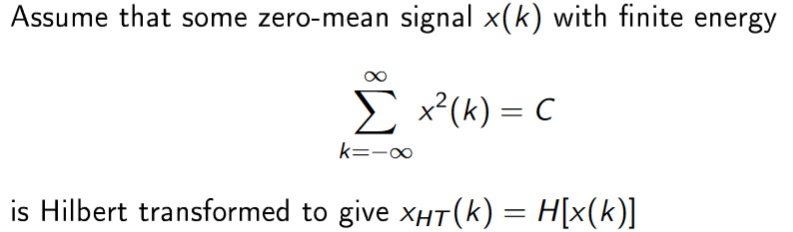

Example:

        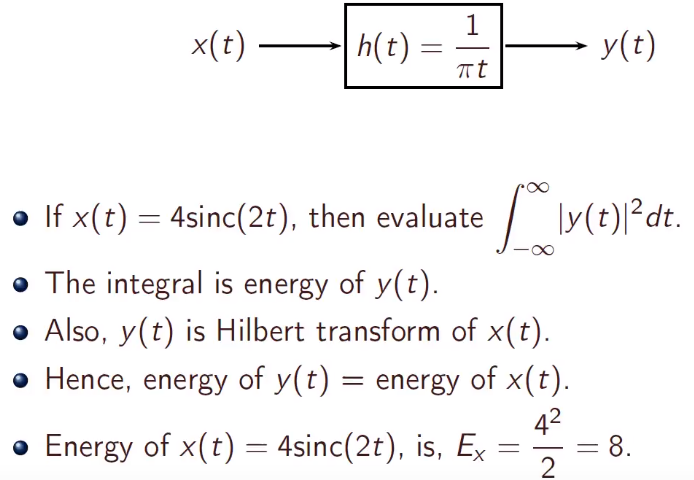

**(6)** The inverse Hilbert transform is $H^{-1} \left\lbrack x_r \left(t\right)\right\rbrack =-H\left\lbrack x_r \left(t\right)\right\rbrack$: